## Strategy Estimation for Las Vegas GP 2023

% Tyres available: C3, C4, C5 - The 3 softest in the Pirelli range.
% Race Duration: 50 laps (305.88km total distance)

% Assumption of tyre pace delta per lap: 0.5s between C5 and C4, and 0.5s
% between C4 and C3. With C5 being the fastest.

% Assumption of degradation per lap: Fuel corrected laptime increase
% linearly as tyre wears (linear tyre deg model assumed due to lack 
% of detailed information on compounds)

% Fuel correction assumption for 110kg of fuel to last 50 laps and 0.035s
% laptime gain per 1kg of fuel burn.

% Initial flying lap pace assumed due to lack of race historical data. 

Calculating Fuel Correction Factor

fuelQuantity = 110;  %kg
totalLapNumber = 50; %laps
lapNumber = 1:50;
timePerKg = 0.035;   %seconds

fuelConsumption = fuelQuantity/totalLapNumber;   %kg/lap

fuelCorrectionFactor = fuelConsumption .* timePerKg; %seconds/lap

fuelLapCorrections = fuelCorrectionFactor .* (lapNumber-1);

Defining Tyre Wear Factors

c5Wear =0.155 %s/lap

c5Wear = 0.1550

c4Wear =0.115 %s/lap

c4Wear = 0.1150

c3Wear =0.1 %s/lap

c3Wear = 0.1000


tyreAge = 1:50; %laps

Calculating Tyre Degradation Laptime Impact

c5InitialLaptime = 95;   %seconds
c4InitialLaptime = 95.5; %seconds
c3InitialLaptime = 96;   %seconds

c5TyreDegLaptime = c5InitialLaptime + c5Wear .* (tyreAge-1);
c4TyreDegLaptime = c4InitialLaptime + c4Wear .* (tyreAge-1);
c3TyreDegLaptime = c3InitialLaptime + c3Wear .* (tyreAge-1);

Calculating Tyre and Fuel Effected Laptimes

c5Laptime = c5InitialLaptime + (c5Wear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);
c4Laptime = c4InitialLaptime + (c4Wear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);
c3Laptime = c3InitialLaptime + (c3Wear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);

Defining Average Pit Time Loss

pitTime = 20;  %seconds

Plot Laptimes for Tyre Compounds Over Full Distance. 

This will be our estimated tyre model, from which we can devise strategy configurations and plot their corresponding race times.

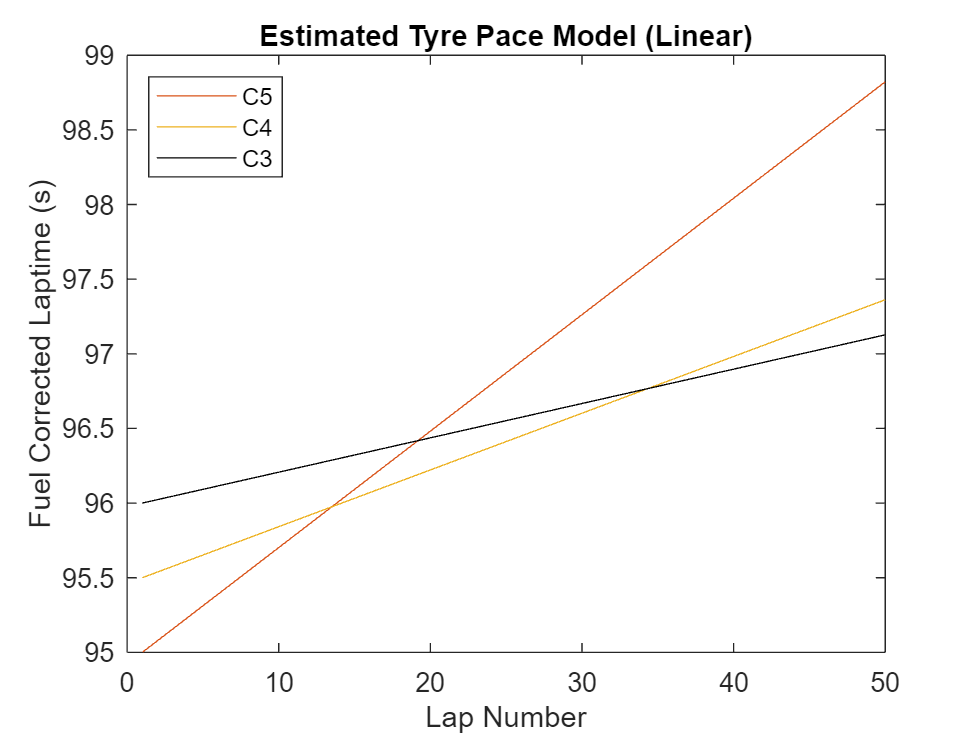

plot(lapNumber,c5Laptime,"Color","#D95319")
hold on
plot(lapNumber,c4Laptime,"Color","#EDB120")
plot(lapNumber,c3Laptime,"Color","#000000")
xlabel("Lap Number")
ylabel("Fuel Corrected Laptime (s)")
title("Estimated Tyre Pace Model (Linear)")
legend(["C5" "C4" "C3"],"Location","northwest")
hold off

Consider a single stop strategy. C5 to C4 (soft to medium).

pitLap = 20

pitLap = 20

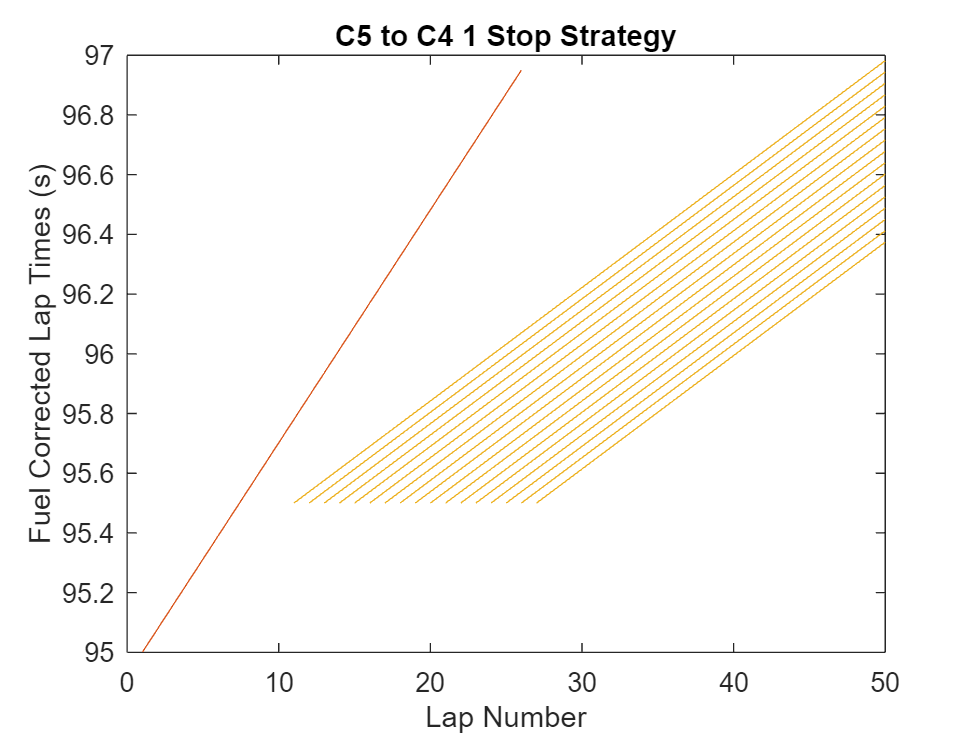

%pitLap = 10:20

% Lets try a loop for pitlaps in range 9 to 18 - should indicate the
% optimal and show a safety car window.

%c5Laptime(tyreAge(1:pitLap))
plot(lapNumber(1:pitLap), c5Laptime(tyreAge(1:pitLap)),"Color","#D95319")
hold on
%c4Laptime(tyreAge(1:(50-pitLap)))
plot(lapNumber(pitLap+1:50), c4Laptime(tyreAge(1:(50-pitLap))),"Color","#EDB120")
xlabel("Lap Number")
ylabel("Fuel Corrected Lap Times (s)")
title("C5 to C4 1 Stop Strategy")


totalRaceTime = sum(c5Laptime(tyreAge(1:pitLap))) + sum(c4Laptime(tyreAge(1:(50-pitLap)))) + pitTime  %seconds

totalRaceTime = 4.8163e+03